## Data Selection

trailingXMonths = 12; % Trailing X Months (TXM) analysis will be computed below, for specified X months (which are valid/available)
includeCurrentMonth = true;

Identify range of days included within Trailing X Months window:

endDate = datetime("now");
startDate = endDate - calmonths(trailingXMonths-1);
endDate = endDate - calmonths(1)*~includeCurrentMonth;

dateRange = datetime(startDate:endDate); %unclear why datetime cast needed

Create equal-length month/year arrays identifying trailing X months here: 

[monthsTXM, idx] = unique(month(dateRange),'stable'); 
yearsTXM = year(dateRange(idx));
numMonthsStudy = numel(monthsTXM);

## Data Access & Cleaning

#### Read workbook

setenv('AWS_DEFAULT_REGION','us-east-2');
T = readtable('s3://vijayiyer05-me-health-metrics/Steps.csv','TextType',"string",'ReadRowNames',true);

#### Clean Variable Names

% Steps variable (column 2)
Tclean = renamevars(T,"Actual","Steps");

#### Create Trailing X Month table 

monthsTXMStr = unique(month(datetime(0,monthsTXM,1),"shortname"),'stable');
TTrailingX = Tclean(contains(string(Tclean.Row),monthsTXMStr),:)

TTrailingX = 12x1 table
                  Steps   
                __________

    Apr 2023    1.1648e+05
    May 2023    1.2386e+05
    Jun 2023    1.3692e+05
    Jul 2023    1.4252e+05
    Aug 2023      1.48e+05
    Sep 2023    1.9303e+05
    Oct 2023     2.068e+05
    Nov 2023     1.474e+05
    Dec 2023    1.3943e+05
    Jan 2024    1.7797e+05
    Feb 2024    1.3428e+05
    Mar 2024    1.1112e+05


## Trailing X Months Visualization

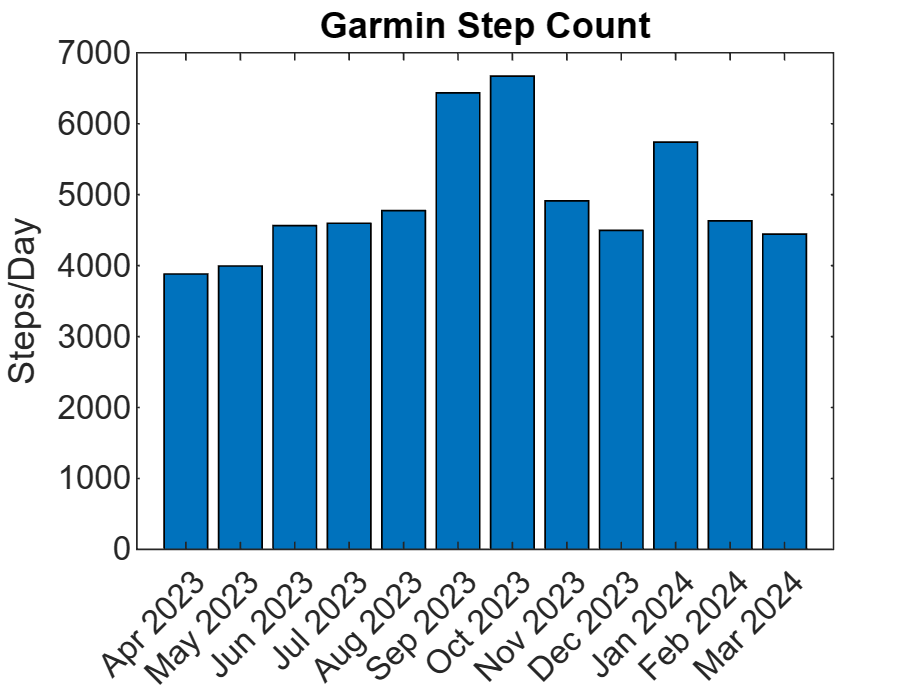

%monthsTXMCat = categorical(monthsTXMStr);
%monthsTXMCat = reordercats(monthsTXMCat,TTrailingX.Row);

daysPerMonth = eomday(yearsTXM,monthsTXM)';

% Handle mid-month case
if includeCurrentMonth
    daysPerMonth(end) = day(endDate);
end

%TODO: Handle skip days by cross-referencing incapacity episodes file

bar(TTrailingX.Row,TTrailingX.Steps./daysPerMonth);
ylabel("Steps/Day")
title("Garmin Step Count")